# Seminar 8 - Extended Kalman filter (EKF) and iterated EKF (IEKF)

**Authors:** Ing. David Vošahlík, prof. Ing. Vladimír Havlena, CSc.

## Introduction

Classical Kalman filter is limited onto a linear system that is rarely to see in real life. Linearization in some operating point could solve the problem for some cases. Fortunately for the rest there are extensions to the kalman filter for nonlinear systems that work better especially when the linearization in neighborhood of the operating point is not sufficient. On the other hand these are more computationaly extensive, harder to implement and consume more resources. Inbetween such methods are e.g. extenended kalman filter EKF and it's iterated version IEKF. These will be studied in this seminar. 

Main idea of EKF is to linearize the system in the current state and input. Iterated EKF just adds more iterations of EKF data steps until the difference of the state estimate in one data step is negligible.  

## Battery state of charge estimation - EKF, IEKF and KF

Let's consider a Li-ion battery that is described by the following equations


$$\begin{array}{l}
\frac{\mathrm{d}\;i}{\mathrm{d}\;t}=10\left(u-i\right)\;+\frac{{\mathrm{dw}}_1 }{\mathrm{dt}}\;,\\
\dot{\mathrm{SOC}} =\frac{1}{Q_r }i+\frac{{\mathrm{dw}}_2 }{\mathrm{dt}}
\end{array}$$


where $i$ is current of the battery, $Q_r$ is capacity of the battery, SOC is state of charge, $\mathbf{dw}~N\left(0,Q_c \right)$ is process noise and $u$ is commanded current. Parameters of the system will be stated directly in the pre-prepared script. Input to the system is also prepared for you. Let's define the state of the battery as $x=\left\lbrack \begin{array}{c}
i\\
\textrm{SOC}
\end{array}\right\rbrack$. Assume that we are able to measure open circuit voltage of the battery. So the measurement eaution is:

$y=\textrm{OCV}\left(\textrm{SOC}\right)+e=h\left(x\right)$,

where $\textrm{OCV}\left(\textrm{SOC}\right)$ is function fitted on the data provided by the battery manufacturer (or measured in test cell) and $e$ is measurement noise. Both the measurement and process noise covariances (Q and R) are valued in the pre-prepared script.

Your task will be:

- Discretize the system (e.g. using euler method)

- Simulate the system

- Implement the extended kalman filter EKF

- Implement the iterated extended kalman filter IEKF

- Implement the clasical kalman filter KF

- Compare the estimates (plot the estimates and print the resulting RMSE) for KF, EKF and IEKF

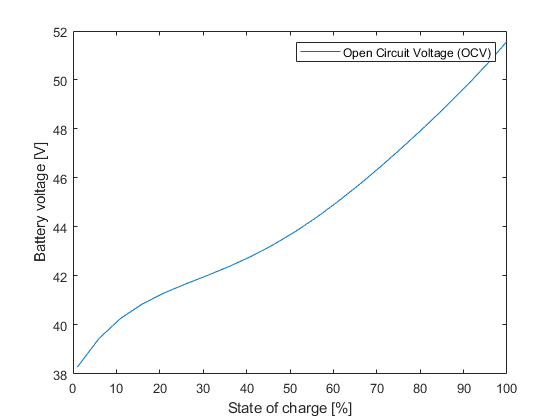

N = 100;                                            % num of steps
Ts = 0.01;                                          % time step
C_AH = 2;                                           % Ah
Qr = C_AH*36;                                       % Convert to charging constant
taui = 10;                                          % time constant for current tracking

Qd  = 0.1*[Ts^3/3 Ts^2/2; Ts^2/2 Ts];               % process noise covariance in discrete time
R  = 0.001;                                         % measurement noise covariance
QL = chol(Qd,'lower');

% IMPLEMENT Nonlinear system functions - h already prepared

h = @(x,e)(38 + 0.295*x(2) - 0.01*x(2)^2 + 1.9694e-04*x(2)^3 - 1.652e-06*x(2)^4 + 5.234e-09*x(2)^5 + sqrt(R)*e);

% IMPLEMENT - it is also appropriate to determine the jacobians of the
% system as function (used more than once in EKF and IEKF)

SOC = [1:5:100 100];
OCV = zeros(numel(SOC), 1);
for i = 1:numel(SOC)
    OCV(i) = h([0 SOC(i)], 0);
end
figure;
plot(SOC, OCV);
legend('Open Circuit Voltage (OCV)');
ylabel('Battery voltage [V]');
xlabel('State of charge [%]')

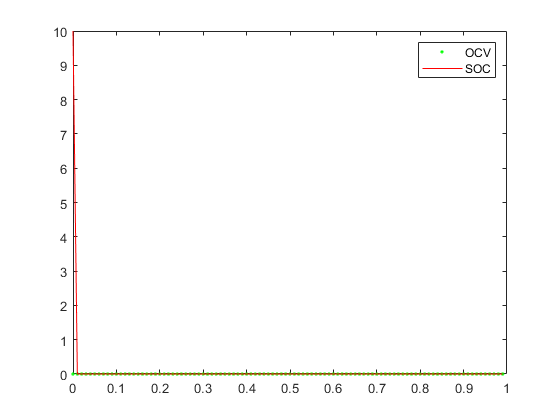


% Init
T = (0:N-1)*Ts;     % time samples
X = zeros(2,N);
Y = zeros(1,N);
U = 40*abs(randn(1,N));

% Simulate
x0 = [1;10];
X(:,1) = x0;

% IMPLEMENT the simulation of the system

% Plot simulation
figure;
plot(T,Y,'g.',T,X(2,:),'r-');
legend('OCV', 'SOC');

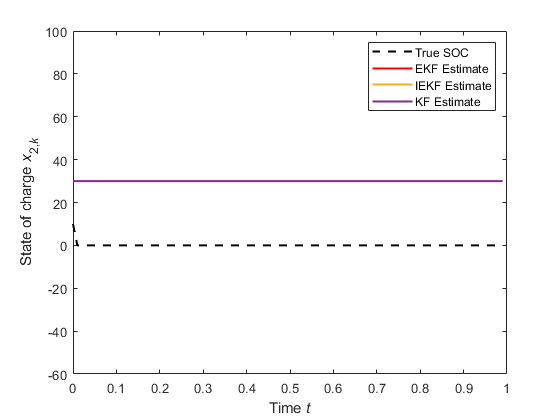


%% EKF

x0 = [4;30];       % Slightly off
P0 = 3*eye(2);

% IEKF

% KF
xp = [40; 10];          % operating point for the KF algorithm

% IMPLEMENT the linearization of the system in xp operating point

% initialize
xhat_EKF = x0;
xhat_KF = x0;
P_EKF = P0;
P_IEKF = P0;
P_KF = P0;
XXhat_EKF = zeros(size(xhat_EKF,1),length(Y));
XXhat_IEKF = zeros(size(xhat_EKF,1),length(Y));
XXhat_KF = zeros(size(xhat_EKF,1),length(Y));
PP = zeros(size(P_EKF,1),size(P_EKF,2),length(Y));


for k=1:length(Y)
    
    % Data step EKF
    % IMPLEMENT the EKF data step
    
    % Data step IEKF
    % IMPLEMENT the IEKF data step
    
    % Data step KF
    % IMPLEMENT the KF data step
    
    
    % Time step EKF
    % IMPLEMENT the EKF time step
    xhat_EKF = x0;
    
    
    % Time step IEKF
    % IMPLEMENT the IEKF time step
    xhat_IEKF = x0;
    
    % Time step KF
    % IMPLEMENT the KF time step
    xhat_KF = x0;
    
    XXhat_EKF(:,k) = xhat_EKF;
    XXhat_IEKF(:,k) = xhat_IEKF;
    XXhat_KF(:,k) = xhat_KF;
    PP(:,:,k) = P_EKF;
end

% IMPLEMENT the computation of RMSE for each estimate

figure;
p=plot(T,X(2,:),'--k',T,XXhat_EKF(2,:),'r', T,XXhat_IEKF(2,:), T,XXhat_KF(2,:), 'Linewidth',1.5);
legend('True SOC','EKF Estimate', 'IEKF Estimate', 'KF Estimate');
xlabel('Time{\it t}');
 ylabel('State of charge {\it{x}}_{2,{\it{k}}}')
 ylim([-60 100]);

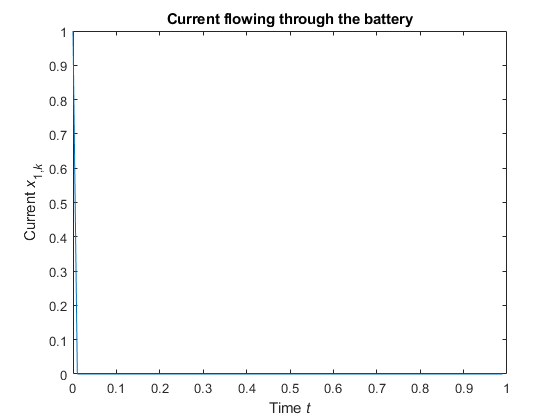


figure;
plot(T, X(1,:));
title('Current flowing to the battery')
xlabel('Time{\it t}');
 ylabel('Current {\it{x}}_{1,{\it{k}}}')